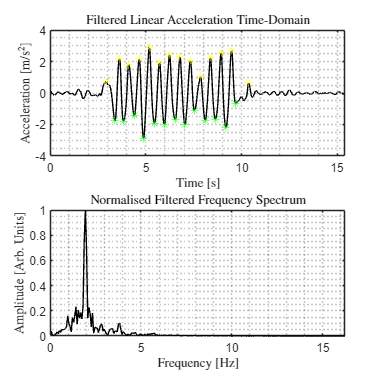

clear
clc
set(0,'defaulttextinterpreter','latex');
walking_data = dlmread('tp_fast_1.txt', '\t'); %#ok<DLMRD>
filt_data = walking_data(:,1);
numSamples = length(filt_data);
Ts = 0.0077;  % Sampling period
fs = 1/Ts; % Sampling frequency

% Time parameters
time_elapsed = Ts * numSamples;
t = (0:Ts:Ts * numSamples - Ts);

% Compute the Fourier Transform
frequencies = (fs/numSamples*(1:numSamples / 2));
ft_filtered = fft(filt_data);
max_amplitude_filtered = max(abs(ft_filtered));
norm_amplitude_filtered = abs(ft_filtered(1:numSamples / 2)) / max_amplitude_filtered;

% Find peaks in filtered data
[maxtab, mintab] = peakdet(filt_data, 0.8, t);

% Plot colours
Gray = [.5 .5 .5];
RGB_Violet = [0.4940 0.1840 0.5560];
RGB_Maroon = [0.6350 0.0780 0.1840];
RGB_Yellow = [0.9290 0.6940 0.1250];
RGB_Orange = [0.8500 0.3250 0.0980];
RGB_Forest = [0.4660 0.6740 0.1880];
RGB_Blue = [0 0.4470 0.7410];

% Create the plot
figure(1);
subplot(2, 1, 1);
plot(t, filt_data, 'LineWidth', 0.5, 'Color', 'k');
title('Filtered Linear Acceleration Time-Domain');
xlabel('Time [s]');
ylabel('Acceleration  [$\mathrm{m/s^2}$]');
grid minor;
xlim([0 time_elapsed]);
hold on; 
plot(mintab(:,1), mintab(:,2), 'g*');
plot(maxtab(:,1), maxtab(:,2), 'y*');
hold off;

subplot(2, 1, 2);
plot(frequencies, norm_amplitude_filtered, 'LineWidth', 0.5, 'Color', 'k');
title('Normalised Filtered Frequency Spectrum');
xlabel('Frequency [Hz]');
ylabel('Amplitude [Arb. Units]');
grid minor;
xlim([0 max(frequencies)/4]);

% Adjust the size of the entire figure
% zset(gcf, 'Position', [100, 100, 800, 800]); % Corrected function name from 'zset' to 'set'
set(gcf, 'Position', [100, 100, 800, 800]);


% Compute Weinberg coefficient using least squares fit
% Define the model function for step length as a function of k and acceleration difference
modelFun = @(k, accelDiff) k .* (accelDiff).^0.25; % Using .^ for element-wise power

% Determine the smaller number of rows between maxtab and mintab
minRows = min(size(maxtab, 1), size(mintab, 1));

% Use only up to minRows of data from both maxtab and mintab for operations
maxPointsSubset = maxtab(1:minRows, :);
minPointsSubset = mintab(1:minRows, :);

% Now you can perform subtraction or any operation on the subsets
% For example, calculating the differences in acceleration for each stride
accelDiffs = maxPointsSubset(:, 2) - minPointsSubset(:, 2);

actual_step_length = 0.6; % Constant actual step length
actual_step_lengths = actual_step_length * ones(size(maxPointsSubset, 1), 1); % Vector of actual step lengths

% Initial guess for k
initialGuess = 0.4;

% Perform the least squares fit
options = optimset('Display','off'); % Suppress lsqcurvefit output
k_fit = lsqcurvefit(modelFun, initialGuess, accelDiffs, actual_step_lengths, [], [], options);

% Print the fitted value of k
fprintf('Fitted k value: %f\n', k_fit);

Fitted k value: 0.429326



% You can compare the fitted step lengths with actual step lengths
fitted_step_lengths = modelFun(k_fit, accelDiffs);

% Compute the error (optional)
error = actual_step_lengths - fitted_step_lengths;
rmse = sqrt(mean(error.^2));
fprintf('Root Mean Square Error (RMSE): %f\n', rmse);

Root Mean Square Error (RMSE): 0.030836


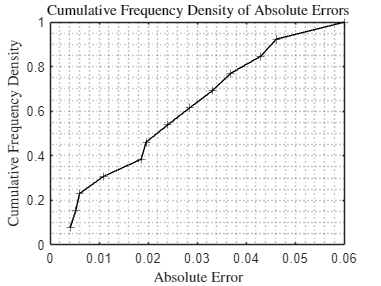


% Total time calculation
t_total = maxtab(end, 1) - maxtab(1, 1); % Corrected from maxtab(2, 1) to maxtab(1, 1) to include the first peak

% Compute the absolute value of the errors
absErrors = abs(error); % Convert all errors to positive by taking the absolute value

% Compute the cumulative frequency density for the absolute errors
sortedAbsErrors = sort(absErrors); % Sort the absolute errors in ascending order
cdfAbsErrors = (1:length(sortedAbsErrors))' / length(sortedAbsErrors); % Calculate the CDF

% Create the cumulative frequency density plot for absolute errors
figure; % Create a new figure
plot(sortedAbsErrors, cdfAbsErrors, '+-', 'LineWidth', 0.5, 'Color', 'k'); % Use stairs to create a step plot
xlabel('Absolute Error');
ylabel('Cumulative Frequency Density');
title('Cumulative Frequency Density of Absolute Errors');
xlim([0 max(sortedAbsErrors)]);
ylim([0 1]); % CDF should range from 0 to 1
grid minor; % Add grid for easier visualization

function [maxtab, mintab]=peakdet(v, delta, x)
%PEAKDET Detect peaks in a vector
%        [MAXTAB, MINTAB] = PEAKDET(V, DELTA) finds the local
%        maxima and minima ("peaks") in the vector V.
%        MAXTAB and MINTAB consists of two columns. Column 1
%        contains indices in V, and column 2 the found values.
%      
%        With [MAXTAB, MINTAB] = PEAKDET(V, DELTA, X) the indices
%        in MAXTAB and MINTAB are replaced with the corresponding
%        X-values.
%
%        A point is considered a maximum peak if it has the maximal
%        value, and was preceded (to the left) by a value lower by
%        DELTA.

% Eli Billauer, 3.4.05
% This function is released to the public domain; Any use is allowed.

maxtab = [];
mintab = [];

v = v(:); % Just in case this wasn't a proper vector

if nargin < 3
  x = (1:length(v))';
else
  x = x(:);
  if length(v)~= length(x)
    error('Input vectors v and x must have same length');
  end
end

if (length(delta(:)))>1
  error('Input argument DELTA must be a scalar');
end

if delta <= 0
  error('Input argument DELTA must be positive');
end

mn = Inf; mx = -Inf;
mnpos = NaN; mxpos = NaN;

lookformax = 1;

for i=1:length(v)
  this = v(i);
  if this > mx, mx = this; mxpos = x(i); end
  if this < mn, mn = this; mnpos = x(i); end

  if lookformax
    if this < mx-delta
      maxtab = [maxtab ; mxpos mx]; %#ok<AGROW> 
      mn = this; mnpos = x(i);
      lookformax = 0;
    end
  else
    if this > mn+delta
      mintab = [mintab ; mnpos mn]; %#ok<AGROW>
      mx = this; mxpos = x(i);
      lookformax = 1;
    end
  end
end
end
